## Determining the elevation changes inside grides with ORM,ACM,FHM_1,FHM_2,FFM & IAM methods

Data source：Altemetry data from CS2 from 2011 to 2020

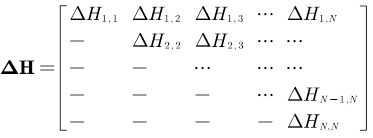

**Content:**

1. Preference

2. Search for all crossovers inside a certain grid

3. Determining the average elevation changes inside the certain grid

4. Constructing elevation changes series by different methods

    4.1 ORM

    4.2 ACM

    4.3 FHM_1

    4.4 FFM

    4.5 IAM

5. Searching for crossovers within all periods inside all 5*5km grids

6. 计算得到每个格网的高程变化

7.

### 1. **Preference**

CurrentPath: ...\Project\Crossover

Region='Ross'; baseline='D';  

%区域所在文件夹相对路径
regionFolder=strcat('.\Variate\',Region,'\');
load(strcat(strcat('.\Variate\',Region,'\边界数据\'),Region,'Boundary.mat'));   % boundary data
load(strcat(strcat('.\Variate\',Region,'\'),Region,'Grid5_5km.mat'));           % grid data


yearNum=10;              % the total of years
matSize=yearNum*12;      % matrix's size 

The time1(year/month) and time2 corresponding to the cell in the dhMat.

% different determination of the time1 and time2 mateix

ym1Mat=zeros(matSize,matSize);  % rows of the elevation-change matrix 
for i=1:matSize-1
    for j=i+1:matSize 
        if mod(i,12)==0
          ym1Mat(i,j)=201000+ceil(i/12)*100+12;        
        else
          ym1Mat(i,j)=201000+ceil(i/12)*100+mod(i,12);        
        end
    end
end

ym2Mat=zeros(matSize,matSize);  % column of the elevation-change matrix
for i=1:matSize-1
    for j=i+1:matSize
         if mod(j,12)==0
             ym2Mat(i,j)=201000+ceil(j/12)*100+12;
         else
             ym2Mat(i,j)=201000+ceil(j/12)*100+mod(j,12);
         end     
    end
end

% 定义一个字符串数组 varList，包含需要保留的变量名
Grid_Name=strcat(Region,'Grid5_5km');
varList = {'matSize', 'ym2Mat', 'ym1Mat', Grid_Name, 'Region', 'baseline'};

% 使用 who 函数获取当前工作空间中的所有变量
allVars = who;

% 确定不在 varList 列表中的所有变量
varsToClear = setdiff(allVars, varList);

% 清除不在 varList 列表中的所有变量
clear(varsToClear{:},'varsToClear');

### 2.Searching for all crossovers inside a certain grid. 

specificGrid=[195,-80.5];             % Central point of certain grid
longGap=2; latGap=1;                  % Grid size = longGap * latGap

dhMat=cell(matSize,matSize,2);

GridCro= struct('AD_Crossovers',[],'DA_Crossovers',[]); 

    % the matrix including crossovers inside grids
DataSourcePath=strcat('.\Variate\',Region,'\','baseline_',baseline,'\');   

for ii=1:matSize-1
    
     disp(ii);
     path=strcat(DataSourcePath,'CP\','row_',num2str(ii,'%03d'),'\');
     
     for jj=ii+1:matSize
       
        ym1=string(ym1Mat(ii,jj));   % time1 
        ym2=string(ym2Mat(ii,jj));   % time2 
        CP_Period=strcat(Region,'_',ym1,'_',ym2); 
                
        load(strcat(path,CP_Period));
        eval(strcat('CP=',CP_Period,';'));
        
        coor=cell2mat({CP(:).coordinate});
        long=coor(1:2:size(coor,2)-1).';
        lat=coor(2:2:size(coor,2)).';
        
        dhMat(ii,jj,:)=SearchPointsInGrid(specificGrid,[longGap,latGap],[long,lat],CP,jj-ii);  % 交叉点高程变化阈值为12m            
        clear(CP_Period);
        
     end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119




GridCro.AD_Crossovers= dhMat(:,:,1);
GridCro.DA_Crossovers= dhMat(:,:,2);

### 3. Determining the average elevation changes by A-D and D-A crossovers inside the grid. 

dhMat1=dhMat(:,:,1);   % the matrix including A-D crossovers
dhMat2=dhMat(:,:,2);   % the matrix including D-A crossovers

numCPMat=zeros(matSize,matSize);   % the matrix including points' number inside every grid
dhMeanMat=zeros(matSize,matSize);  
sigmaMat=zeros(matSize,matSize);   % the matrix including standard deviation of every delta_h

for ii=1:matSize-1
    for jj=ii+1:matSize
        adEleDif= cell2mat(dhMat(ii,jj,1));
        daEleDif= cell2mat(dhMat(ii,jj,2));
             
        % Error processing: Remove the maximum and minimun from data of
        % this period(ii, jj)
        
        maxVal=max([adEleDif;daEleDif]);
        minVal=min([daEleDif;adEleDif]);
        
        adEleDif(adEleDif==maxVal)=[];
        adEleDif(adEleDif==minVal)=[];
        daEleDif(daEleDif==maxVal)=[];
        daEleDif(daEleDif==minVal)=[];
        
        if isempty(adEleDif)
            nAD=0;
            std_AD=0;
        else
            nAD=size(adEleDif,1);
            std_AD=std(adEleDif);
        end
        
        if isempty(daEleDif)
            nDA=0;
            std_DA=0;
        else
            nDA=size(daEleDif,1);
            std_DA=std(daEleDif);
        end
        
        nt=nAD+nDA;
        
        omega_AD=nAD/(nAD+nDA);
        omega_DA=nDA/(nAD+nDA);       
        sigmaMat(ii,jj)=sqrt(omega_AD^2*std_AD^2+omega_DA^2*std_DA^2); % standard deviation
        numCPMat(ii,jj)=size(adEleDif,1)+size(daEleDif,1);
        
        if nAD==0||nDA==0
          dhMeanMat(ii,jj)=mean([adEleDif;daEleDif]);
        else
          dhMeanMat(ii,jj)=mean(adEleDif)*nAD/(nAD+nDA)+mean(daEleDif)*nDA/(nAD+nDA);
        end 
    end
end

dhMeanMat=dhMeanMat*100;  % from "m" to "cm"
sigmaMat=sigmaMat*100;

% clearvars -except dhMeanMat sigmaMat matSize dhMat dhMat1 dhMat2 numCPMat;

% searching for Nan inside the matrix
[i,j]=find(isnan(dhMeanMat));
[ii,jj]=find(isnan(sigmaMat));

### 4. Constructing elevation changes series by different methods

#### **    4.1 ORM**

ORM=dhMeanMat(1,:).';
sigma_ORM=sigmaMat(1,1:120).';

#### **    4.2 ACM**

ACM=zeros(matSize,1);
sigma_ACM=zeros(120,1);

for ii=1:matSize-1
       jj=ii+1;
       dia(ii)=dhMeanMat(ii,jj);
       ACM(ii+1)=ACM(ii)+dhMeanMat(ii,jj);
end
% standard deviation of CPM
temp = [0;diag(sigmaMat,1).*diag(sigmaMat,1)];
for ii=2:120
    sigma_ACM(ii)=sqrt(sum(temp(1:ii)));
end

#### **4.3 FHM_1**

% FHM1=zeros(matSize,1);
% FHM1_Mat=dhMeanMat;
% FHM1(2)=dhMeanMat(1,2);
% 
% for c=3:matSize  % column 
%     for r=2:c-1  % row
%         FHM1_Mat(r,c)=FHM1(r)+FHM1_Mat(r,c); 
%     end
%         FHM1(c)=sum(FHM1_Mat(:,c))/(c-1);
% end

% 计算FHM1算法按j-1赋权的系数

sigma_FHM1=zeros(120,1);
CoeCellArray = cell(120, 1);
matrix2 = [0, 1; 0, 0];
CoeCellArray{2}=matrix2;

for c=3:120
    disp(c);
    coeMatrix=zeros(c,c);
    for r=1:c-1
        if r==1
             coeMatrix(r,c)= coeMatrix(r,c)+ 1/(c-1);
        else 
             coeMatrix(r,c)= coeMatrix(r,c)+ 1/(c-1);
             coeMatrix(1:r,1:r)=CoeCellArray{r}*1/(c-1)+ coeMatrix(1:r,1:r);
        end
    end
    CoeCellArray{c}= sym(coeMatrix);
end

% 根据观测值的系数计算标准差
for ii=3:120
    
    coeMatrix= CoeCellArray{ii};
    
    
    temp=double(coeMatrix.^2.*(sigmaMat(1:ii,1:ii).^2));
    
    sigma_FHM1(ii)=sqrt(sum(sum()));
end



**4.3 FHM_2**

FHM_Mat=dhMeanMat;
FHM=zeros(matSize,1);

% building a temporary matrix, 
% all elements in the same column in this matrix 
% are their elevation changes relative to the frist period.

for c=3:matSize  % column 
    for r=2:c-1  % row
        FHM_Mat(r,c)=FHM_Mat(1,r)+FHM_Mat(r,c); 
    end
end

for c=2:matSize
    FHM(c)=sum(FHM_Mat(:,c))/(c-1);
end

% determining the standard deviation of FHM
sigma_FHM=zeros(matSize,1);
for i=2:120
    p1=sigmaMat(1,i)^2;
    p2=0;
    if i>2 
        for j=2:i
            p2=p2+sigmaMat(1,j)^2+sigmaMat(j,i)^2;
        end
    end     
    sigma_FHM(i)=sqrt(p1+p2)/(i-1);
end

#### **    4.4 FFM**

Completing the lower triangular matrix is necessary for FFM method 

The number of routes in this method is N-1, and N means the number of period.

FFMat=zeros(matSize,matSize)*nan;   

for i=1:matSize       % row 
    for j=1:matSize   % column 
        if i==1          
            FFMat(i,j)=dhMeanMat(1,j);       
        elseif i>j&&j~=1   
            FFMat(i,j)=dhMeanMat(1,i)-dhMeanMat(j,i); 
        elseif i<j
            FFMat(i,j)=dhMeanMat(1,i)+dhMeanMat(i,j);
        end
    end 
end

val_x=true(120,1);              % 有效参数的个数
for i=1:size(FFMat,2)
    if all(isnan(FFMat(i,:).')&isnan(FFMat(:,i)))
        val_x(i)=0;
    end
end
a=sum(sum(val_x));

FFM=zeros(1,matSize);
for j=2:matSize                      % column   
    temp=FFMat(:,j); 
    index=find(~isnan(temp));        % including valid values only.
    if size(index,1)== 0     
          continue;
    end
    FFM(j)=sum(FFMat(index,j))/size(index,1);   
end

% 计算结果中每个高程变化元素的标准差
sigma_FFH=zeros(matSize-1,1);
for j=2:matSize  % column
      temp=0;
      for i=1:matSize  % row
        if i<j && i==1
            temp=temp+sigmaMat(i,j)^2;  % 第一行元素直接为相对于第一月的高程变化
        elseif i<j && i~=1
            temp=temp+sigmaMat(1,i)^2+sigmaMat(i,j)^2;
        elseif i>j
            temp=temp+sigmaMat(1,i)^2+sigmaMat(j,i)^2;
        end
      end
      sigma_FFH(j)=sqrt(temp)/(matSize-1);
end

FFM=FFM.';

% 0值替换成nan值
FFM(find(FFM==0))=nan;
FFM(1)=0;

#### **    4.5 IAM**

 IAM=iam(dhMeanMat,matSize,FFM,numCPMat); 
 
 numOfEquation=0;

for i=1:size(dhMeanMat,2)-1
    numOfEquation=numOfEquation+i;  % 观测方程个数
end
numOfX=size(dhMeanMat,1)-1;         % 参数个数

% 矩阵中存在数据缺失的情况, 对
valNum=~isnan(dhMeanMat);
numOfEquation=sum(sum(valNum));

% 当该周期不存在观测值时，减少参数的个数，统计缺乏观测值的周期数
val_x=true(120,1);              % 有效参数的个数
for i=1:size(dhMeanMat,2)
    if all(isnan(dhMeanMat(i,:).')&isnan(dhMeanMat(:,i)))
        val_x(i)=0;
    end
end
numOfX=numOfX-size(find(val_x==false),1);

dh=dhMeanMat;

index=1;
for i=1:matSize
   if ~val_x(i)
       dh(index,:)=[];
       dh(:,index)=[];
       index=index-1;
   end
   index=index+1;
end

% 参数近似值首先从FFM选取，其次从dh选取，再设置为0
appro=FFM(:,1).';    
appro(find(isnan(appro)))=dhMeanMat(1,find(isnan(appro)));
appro(isnan(appro))=0;
appro(find(val_x==false))=[];

% appro=FFM(:,1);          % 参数近似值
% appro(find(appro==0))=[];
% appro=[0,appro.'];

% 建立系数矩阵B，矩阵L
B=zeros(numOfEquation,numOfX);
L=zeros(numOfEquation,1);

% 从矩阵第一行从左往右的观测值开始建立观测方程
index=1;      

for i=1:size(dh,1)-1                       % 行数循环
    
     numOfObservations=size(dh,2)-i;       % 行数与该行所对应的观测值个数的关系
     nanNum= sum(isnan(dh(i,i+1:end)));          % 减去数据缺失值，数据缺失值无法建立观测方程
     numOfObservations=numOfObservations-nanNum;
     
     startingColum=1+i;                        % 每行的起始循环列
     for j=startingColum:size(dh,2)            % 列数循环
         if isnan(dh(i,j))
             continue;
         end
         
         if i==1
             B(index,j-1)=1;
             L(index)=0;
         else
             B(index,i-1)=-1;
             B(index,j-1)=1;
             L(index)=appro(1,j)-appro(1,i)-dh(i,j);
         end
         index=index+1;
     end
end
L=-L;


定权 三种不同方式

% 所有观测值默认为等权
% P=diag(ones(numOfEquation,1));

% % 根据每个观测值的标准差确定权矩阵
P=zeros(numOfEquation,numOfEquation);
index=1;
for i=1:size(dhMeanMat,1)-1                       % 行数循环
     startingColum=1+i;                           % 每行的起始循环列
     for j=startingColum:size(dhMeanMat,2)        % 列数循环
        P(index,index)=1/(sigmaMat(i,j)^2); 
        index=index+1;
     end
end

%% 根据交叉点数量重新确定权矩阵
% P=zeros(numOfEquation,numOfEquation);
% index=1;
% for i=1:size(dhMeanMat,1)-1                       % 行数循环
%      startingColum=1+i;                           % 每行的起始循环列
%      for j=startingColum:size(dhMeanMat,2)        % 列数循环
%         if ~isnan(dhMeanMat(i,j))
%             P(index,index)=size(cell2mat(dhMat1(i,j)),1)+size(cell2mat(dhMat2(i,j)),1);    
%             index=index+1;
%         end
%      end
% end

 求解未知参数的最小二乘解

x=inv(B.'*P*B)*B.'*P*L; 

IAM=zeros(matSize,1)*nan;
IAM(1)=0;

index=2;
for i=2:matSize
    if ~val_x(i)
       
    else
        IAM(i)=appro(1,index)+x(index-1);
        index=index+1;
    end
end

V=B*x+L;
Qxx=inv(B.'*P*B);

% 验后单位权中误差
sigma_Post=sqrt((V.'*P*V)/(numOfEquation-(numOfX)));
sigma_IAM=sigma_Post*sqrt(diag(Qxx));

std_IAM=zeros(matSize,1)*nan;
std_IAM(1)=0;
index=1
for i=2:matSize
    if val_x(i)  
        std_IAM(i)=sigma_IAM(index);
        index=index+1;
    end
end


### **5. Searching for crossovers inside each 5*5km grids**

latGap=0.045;  % 所有格网的纬度间距是一致的
grid5_5km = eval([Region 'Grid5_5km']);

Mat=cell(matSize,matSize,1);   
GridCro= struct('long',[], 'lat',[], 'longGap',[],'AD_Crossovers',[],'DA_Crossovers',[]); 
GridCro.AD_Crossovers=Mat;
GridCro.DA_Crossovers=Mat;

GridCro=repmat(GridCro,[size(grid5_5km,1) 1]);

startGrid=1; endGrid=1000;

for ii=1:matSize-1   % 高程变化矩阵行遍历

    path=strcat(DataSourcePath,'CP\','row_',num2str(ii,'%03d'),'\'); 
 
    disp(ii);
    for jj=ii+1:matSize   % 高程变化矩阵列遍历
     
        ym1=string(ym1Mat(ii,jj));   % time1    
        ym2=string(ym2Mat(ii,jj));   % time2  
        CP_Period=strcat(Region,'_',ym1,'_',ym2); 
        load(strcat(path,CP_Period));     
        eval(strcat('CP=',CP_Period,';')); 
        
        coor=cell2mat({CP(:).coordinate});
        long=coor(1:2:size(coor,2)-1).';
        lat=coor(2:2:size(coor,2)).';
    
        for i=startGrid:endGrid   % 格网遍历
                            
            longGap=grid5_5km(i).longGap;              
            specificGrid=[grid5_5km(i).long,grid5_5km(i).lat];               
            cout=SearchPointsInGrid(specificGrid,[longGap,latGap],[long,lat],CP,jj-ii);
           
            if isempty(cout)       % 该期数据在该格网内无交叉点
               continue;
            end
                    
            
            AD_Mat=GridCro(i).AD_Crossovers;
            DA_Mat=GridCro(i).DA_Crossovers;
             
            AD_Mat(ii,jj,:)=cout(:,:,1);
            DA_Mat(ii,jj,:)=cout(:,:,2);
            
            GridCro(i).AD_Crossovers=AD_Mat;   
            GridCro(i).DA_Crossovers=DA_Mat;  
            
        end  
        clear(CP_Period);
    end        
end

beginNum=floor(startGrid/1000);
endNum=endGrid/1000-1;

for j=beginNum:endNum 

    startGrid=1+(j)*1000; endGrid=startGrid+1000-1;
    
fileStoragePath=strcat('.\Variate\',Region,'\所有5_5km格网交叉点数据\Grid_',num2str(startGrid),'_',num2str(endGrid),'\');

if ~exist(fileStoragePath,'dir')
    mkdir(fileStoragePath)
end
    
    for i=startGrid:endGrid 
        
        disp(i);
        GridCro(i).lat=grid5_5km(i).lat;
        GridCro(i).long=grid5_5km(i).long;
        GridCro(i).longGap=grid5_5km(i).longGap;
        
        nameGridCro=strcat('GridCro_',num2str(i));
        fileName=strcat(nameGridCro,'.mat');
        eval(strcat(nameGridCro ,'=GridCro(i,:);'));
        save([fileStoragePath,fileName],nameGridCro);
        clear(nameGridCro);         %清除原始数据变量    
    end

end

### ** 6. 计算得到每个格网的高程变化**


latGap=0.045;     % 所有格网的纬度长一致
grid5_5km = eval([Region 'Grid5_5km']);


Mat=zeros(matSize,1)*nan;   
Grid_EC= struct('long',[], 'lat',[], 'longGap',[],'eleChange',[]); 
Grid_EC.eleChange=Mat;
Grid_EC=repmat(Grid_EC,[size(grid5_5km,1) 1]);

Grid_EC_FFM= struct('long',[], 'lat',[], 'longGap',[],'eleChange',[]); 
Grid_EC_FFM.eleChange=Mat;
Grid_EC_FFM=repmat(Grid_EC_FFM,[size(grid5_5km,1)  1]);

% 设置起始和结束的格网编号
startGrid=1; endGrid=1000;

% 循环遍历每一个格网
    for i=startGrid:endGrid
        
        % 构造要读取的文件名
        nameGridCro=strcat('GridCro_',num2str(i));  
        
        % 计算文件所在的文件夹起始编号
      
        folder_Num=1+(floor((i-1)/1000))*1000; 
        
        % 构造文件夹路径
        folder_name = ['.\Variate\' Region '\所有5_5km格网交叉点数据\Grid_'  num2str(folder_Num) '_' num2str(folder_Num+999)];  % 文件夹名字
        
        
        % 读取文件
        load(fullfile(folder_name, strcat(nameGridCro,'.mat')));
        

        disp(i);        
        temp=eval(nameGridCro);
             
        dhMat1=temp.AD_Crossovers;
        dhMat2=temp.DA_Crossovers;
        
        numCPMat=zeros(matSize,matSize);   % the matrix including total points inside every grid
        dhMeanMat=zeros(matSize,matSize)*nan;
        sigmaMat=zeros(matSize,matSize);
        
        for ii=1:matSize-1
            for jj=ii+1:matSize
                adEleDif= cell2mat(dhMat1(ii,jj));
                daEleDif= cell2mat(dhMat2(ii,jj));
                
                if isempty(adEleDif)
                    nAD=0;
                    std_AD=0;
                else
                    nAD=size(adEleDif,1);
                    std_AD=std(adEleDif);
                end
                
                if isempty(daEleDif)
                    nDA=0;
                    std_DA=0;
                else
                    nDA=size(daEleDif,1);
                    std_DA=std(daEleDif);
                end
                
                nt=nAD+nDA;
                
                omega_AD=nAD/(nAD+nDA);
                omega_DA=nDA/(nAD+nDA);       
                sigmaMat(ii,jj)=sqrt(omega_AD^2*std_AD^2+omega_DA^2*std_DA^2);
                numCPMat(ii,jj)=size(adEleDif,1)+size(daEleDif,1);
                
                if nAD==0||nDA==0
                  dhMeanMat(ii,jj)=mean([adEleDif;daEleDif]);
                else
                  dhMeanMat(ii,jj)=mean(adEleDif)*nAD/(nAD+nDA)+mean(daEleDif)*nDA/(nAD+nDA);
                end 
            end
        end
        
        dhMeanMat=dhMeanMat*100;
        sigmaMat=sigmaMat*100;
          
        FFM=ffm(dhMeanMat,matSize);   % 先通过FFM方法得到的结果作为IAM方法的近似值
        IAM=iam(dhMeanMat,matSize,FFM,numCPMat); 

        Grid_EC(i).lat=grid5_5km(i).lat;
        Grid_EC(i).long=grid5_5km(i).long;
        Grid_EC(i).longGap=grid5_5km(i).longGap;
        Grid_EC(i).eleChange=IAM;  % 注意正常计算此处应当为IAM
        
        Grid_EC_FFM(i).lat=grid5_5km(i).lat;
        Grid_EC_FFM(i).long=grid5_5km(i).long;
        Grid_EC_FFM(i).longGap=grid5_5km(i).longGap;
        Grid_EC_FFM(i).eleChange=FFM;  
        
        clear(nameGridCro);
    end

% clearvars -except dhMeanMat sigmaMat matSize dhMat dhMat1 dhMat2 numCPMat;


% 得到某一期的所有格网的高程变化值


for cycle=2:13

    dh=zeros(size(Grid_EC,1),3)*nan;
    for i=1:size(Grid_EC,1)
        
        dh(i,1)=Grid_EC(i).long;
        dh(i,2)=Grid_EC(i).lat;
        temp=Grid_EC(i).eleChange;
        
        if ~isempty(temp)
           temp=temp(cycle);
              dh(i,3)=temp;
        end
    end
    
    dh(isnan(dh(:,3)),:)=[];
       
    ec=dh(:,3);
    stdDev=std(ec);
    
    % dh(abs(ec)>=(mean(ec)+3*stdDev),:)=[];  
    
    filename=strcat('2011',num2str(cycle,'%02d'),'.txt');
    dlmwrite(filename, dh, 'delimiter', '\t');

end   

figure;
load(".\variate\colorBar\LowBlue_HighRed_ColorMap.mat"); 
colormap(CustomColormap) 
h=scatter(dh(:,1),dh(:,2),12,dh(:,3),'filled');
caxis([-100 100]);


求120期的平均高程变化

dh=zeros(120,17858)*nan;
% 
for i=1:17858
%     disp(i);
     temp=Grid_EC(i).eleChange;
     if ~isempty(temp)
         dh(:,i)=temp.';
     end
end


meanDh=zeros(120,1);
for i=2:120
    temp=dh(i,:);
    temp=temp(~isnan(temp));
    
    stdDev=std(temp);
    meanVal=mean(temp);
    
    temp(temp>=(meanVal+3*stdDev)|temp<=(meanVal-3*stdDev))=[];  
    
    
    meanDh(i)=mean(temp);
end

% 计算某个格网的高程变化率，一次拟合

ec=meanDh;

x = 1:numel(ec);
x(isnan(ec)) = [];
ec(isnan(ec)) = [];

% 进行一次拟合
p = polyfit(x, ec, 1);

yrChange= p(1)*12;